% Given parameters
n = 4;
V_bat = 50;
f_s = 100e3;
L_k = 30e-6;
V_dc = 800;
L = 80e-6;
I_ZVS2 = 0;
M = 1;
alpha=1e-4;
% Create a mesh grid for D and varphi
D = linspace(0.01, 0.5, 100);  % D in [0, 0.5]
varphi = linspace(0.01, 1, 100); % varphi in [0, 1]
[D_grid, varphi_grid] = meshgrid(D, varphi);  % mesh grid for D and varphi

% Calculate P_N (normalized power) IN(normalized current)
P_N = (n * V_bat * V_dc) / (8 * f_s * L_k);
IN=n*V_bat/(4*f_s*L_k);
% Initialize P_bat
P_bat = zeros(size(D_grid));

% Calculate sigma
sigma = 2 * D_grid.^2 + 4 * D_grid .* varphi_grid - D_grid;


% Loop over each grid point and calculate P_bat
for i = 1:numel(D_grid)
    D_val = D_grid(i);
    varphi_val = varphi_grid(i);
    
    % Apply the conditions and compute P_bat P=Pbat-Pdc=-Ppv
    if varphi_val < 0.5 - D_val
        P_bat(i) = sigma(i) + alpha + ((V_bat^2 * D_val^2 * (1 - D_val)) / (L * f_s) + 2 * (n * IN * (M - 2 * D_val - 4 * M * varphi_val) + I_ZVS2) * D_val * V_bat) / P_N;
    elseif varphi_val >= 0.5 - D_val && varphi_val < 0.5
        P_bat(i) = (-sigma(i) + 2 * D_val - (2 * varphi_val - 1)^2) + alpha + ((V_bat^2 * D_val^2 * (1 - D_val)) / (L * f_s) - 2 * D_val * V_bat * (n * IN * (M - 2 * D_val - 4 * M * varphi_val) + I_ZVS2)) / P_N;
    elseif varphi_val >= 0.5 && varphi_val < 1 - D_val
        P_bat(i) = (-sigma(i) + 2 * D_val) + alpha + ((V_bat^2 * D_val^2 * (1 - D_val)) / (L * f_s) - 2 * (n * IN * (-3 * M - 2 * D_val + 4 * M * varphi_val) + I_ZVS2) * D_val * V_bat) / P_N;
    else
        P_bat(i) = (sigma(i) - 4 * D_val + 4 * (varphi_val - 1)^2) + alpha + ((V_bat^2 * D_val^2 * (1 - D_val)) / (L * f_s) - 2 * (n * IN * (-3 * M - 2 * D_val + 4 * M * varphi_val) + I_ZVS2) * D_val * V_bat) / P_N;
    end
end

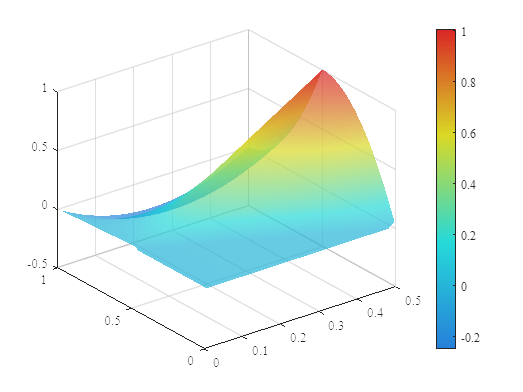

% Plot the results
figure;
surf(D_grid, varphi_grid, P_bat,'FaceAlpha', 0.7);

% 禁用边框线
set(gca, 'FontName', 'Times New Roman');

% 设置颜色映射
n = 256; % 定义颜色分辨率
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ... % 蓝到绿
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ... % 绿到黄
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)'];    % 黄到红
gray_level = 0.5; % 接近灰色的值（0.5是中性灰）
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % 线性插值降低饱和度
colormap(desaturated_cmap);
colorbar;

% 平滑显示
shading interp;  % 平滑插值

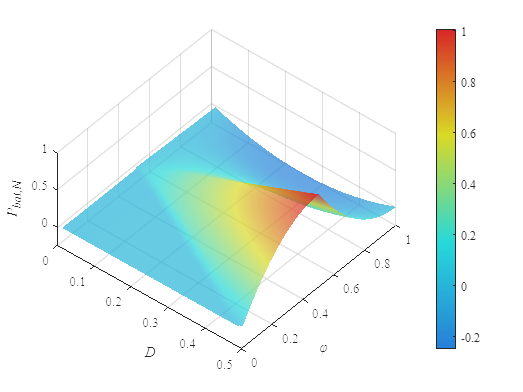


% 设置视角和网格
view(40,60); % 设置视角
grid on;
hold on;

xlabel('\it{D}');
ylabel('\it{φ}');
zlabel('\it{P_{bat,N}}');

colorbar;

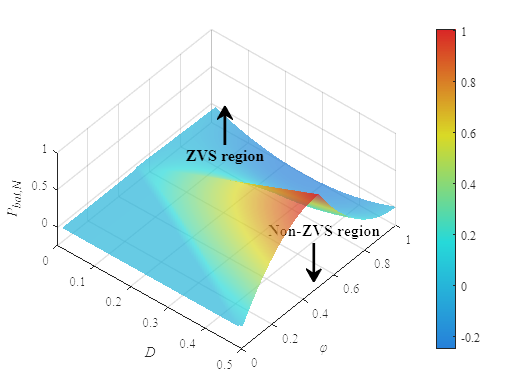


hold on;
%contour3(D_grid, phi_grid, M, [1, 1], 'LineWidth', 2, 'LineColor', 'k');
%text(0.43, 0.7, 0, 'Non-ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
%text(0.25, 0.5, 0.8, 'ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
% 添加箭头
% 注意：annotation的坐标是相对位置的，范围是[0, 1]
% 箭头指离'Non-ZVS Region'文本
%annotation('arrow', [0.6, 0.6], [0.38, 0.28], 'Color', 'black', 'LineWidth', 2);
% 箭头指向'ZVS Region'文本
%annotation('arrow', [0.43, 0.43], [0.63, 0.73], 'Color', 'black', 'LineWidth', 2);
text(0.43, 0.7, 0, 'Non-ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', 'FontWeight', 'bold', 'Color', 'black', 'HorizontalAlignment', 'center');
annotation('arrow', [0.6, 0.6], [0.38, 0.28], 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10, 'Color', 'black');

annotation('textarrow', [0.43, 0.43], [0.63, 0.73], 'String', 'ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', ...
    'FontWeight', 'bold', 'Color', 'black', 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10);

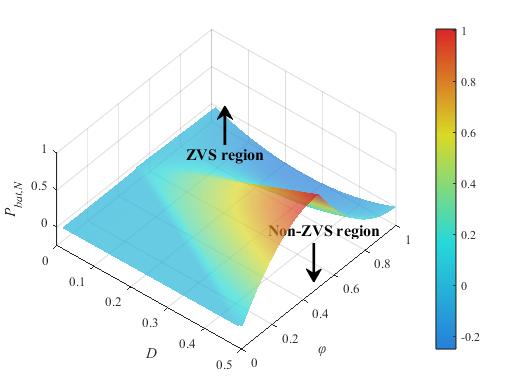

% 导出为 PDF 格式，设置输出尺寸
exportgraphics(gcf, 'ZVSLowVoltageSideS43DMode456.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');